# **Model Aircraft Design Optimization **

*Copyright 2022 The MathWorks, Inc.*

This demonstration optimizes an aircraft with SAE Aero Design's 2020 Regular Class problem statement as an example. A problem based approach is used to construct the design optimization problem. For SAE Aero Design's 2020 Regular Class competition, each team's objective was to maximise their Final Flight Score ($FFS$) which was the sum of three highest Flight Scores (${FS}_i$) and a Payload Prediction Bonus ($PPB$).


$$FFS={FS}_1+{FS}_2+{FS}_3+PPB$$


Each individual Flight Score ($FS$) was calculated as follows


$$FS=120*\frac{2*N_S+W_{BP}}{b_w+l_{cargo}}$$


where,


$$N_s=No.\;of\;Spherical\;Payload\\
W_{BP}=Weight\;of\;Boxed\;Payload(lbs)\\
b_W=Wingspan (in)\\
l_{cargo}=Length\;of\;payload\;bay(in)$$


Therefore, this demo maximizes the following objective as it performs calculations in SI Units. Also, $N_s=1$ as only 1 spherical payload is considered.


$$Objective=120*\frac{2+2.2*W_{BP}}{39.37*(b_w+l_{cargo})}$$


 A problem based approach is used to construct the design optimization problem. All expressions evaluated during problem setup are stored as a hierarchy of structure inside the `aircraft `structure. Four domain specific functions incrementally construct the design problem by modelling domain specific expressions and adding any relevant constraints. Finally, a 12 dimensional optimization problem is obtained with the following optimization variables.

        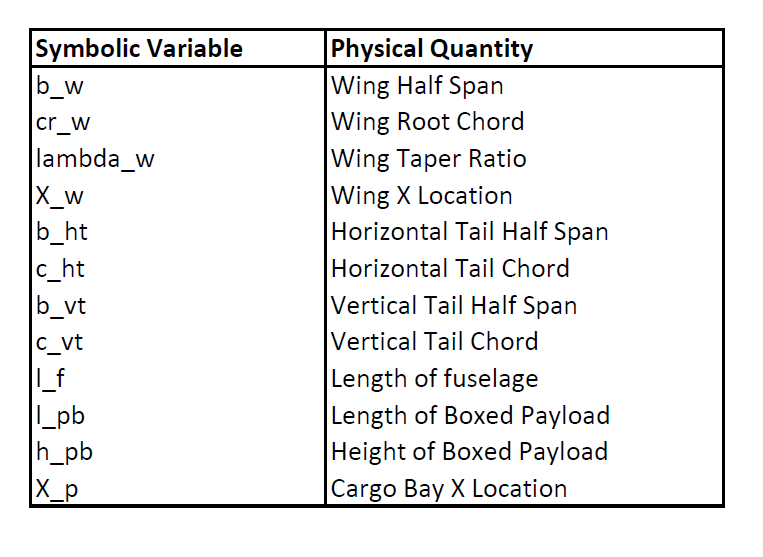

Following is the representation of optimization variables for clearer understanding.

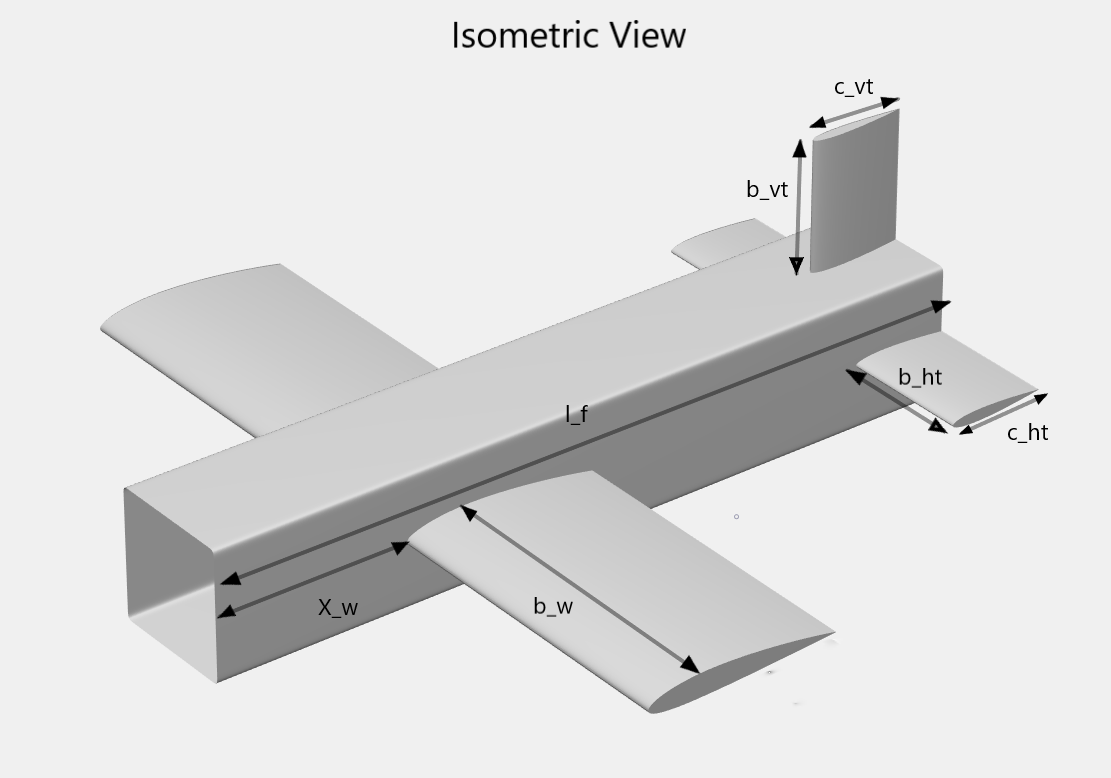 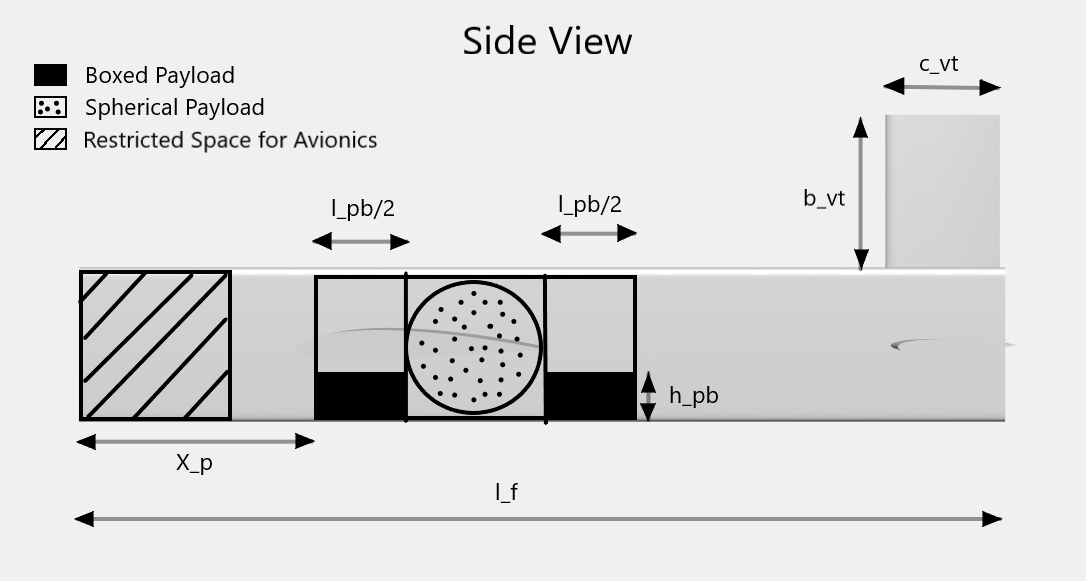 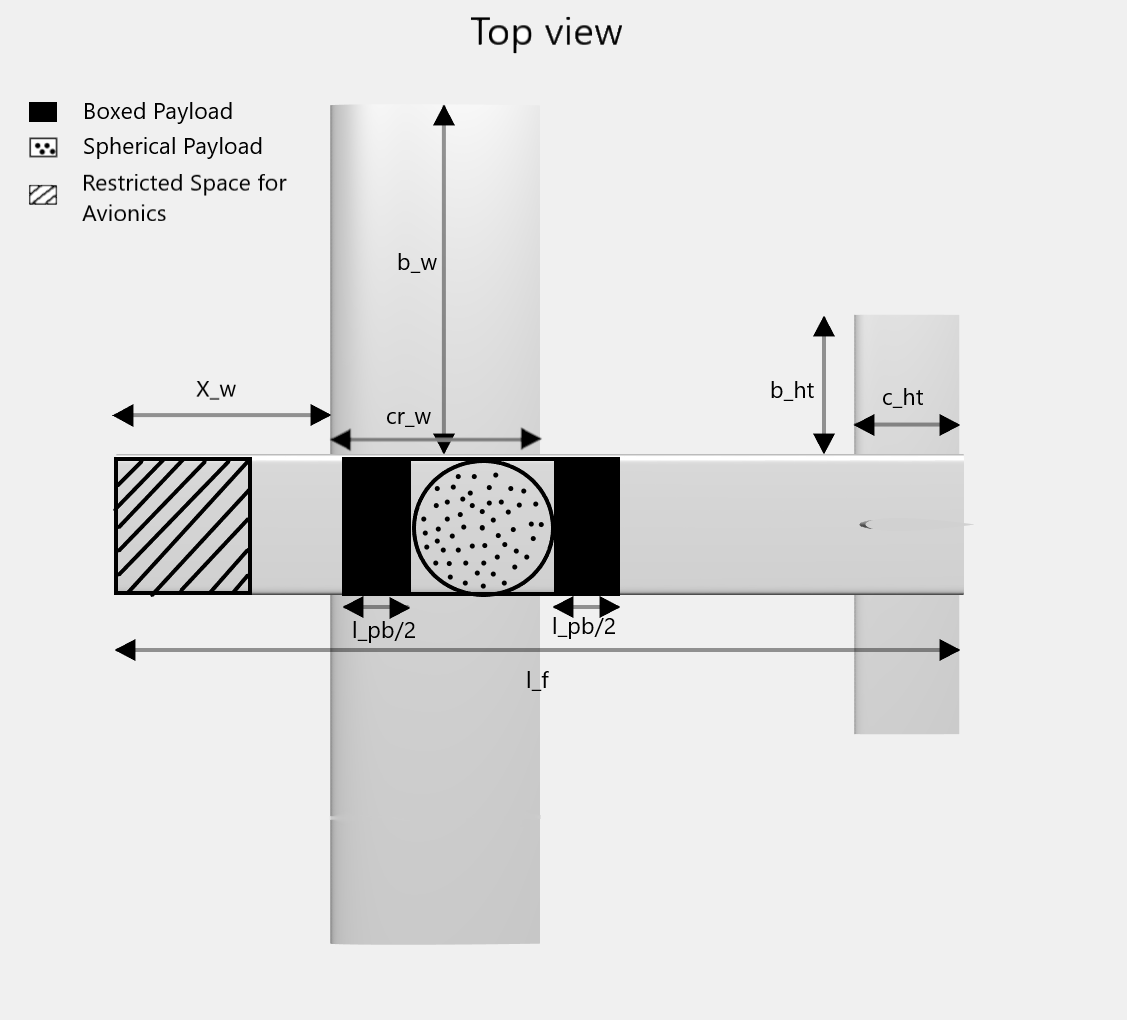

## **Setup the design optimization problem**

% add helper functions to path
addpath('Aerodynamic Coefficients');
addpath('Mass Moment of Inertia');

% setup optimization
designprob = optimproblem('ObjectiveSense','maximize');
[aircraft, wing, fuselage, hTail, vTail, payload, initialValues] = initializeAircraft;
[aircraft, wing, fuselage, hTail, vTail, designprob] = ...
    addAerodynamics(aircraft, wing, fuselage, hTail, vTail, designprob);
[aircraft, wing, fuselage, hTail, vTail, payload, designprob] = ... 
    addWeightAndSizing(aircraft, wing, fuselage, hTail, vTail, payload, designprob);

% Create FixedWing object here so only a single instance is created
[myAircraft, CruiseState] = createFixedWing(aircraft.Mass, wing, hTail, initialValues);

[aircraft, wing, vTail, designprob] = ...
    addStability(aircraft, wing, fuselage, hTail, vTail, payload, designprob,myAircraft,CruiseState);
[aircraft,designprob] = addPerformance(aircraft, wing.PlanformArea, designprob);

% Design objective SAE Aero Design's 2020 Regular Class Flight score
designprob.Objective = 120*(2+2.2*payload.Boxed.Mass)/(39.37*(2*wing.HalfSpan+payload.Length));

## Set options for optimization solver

options = optimoptions(designprob);
options.MaxFunctionEvaluations = Inf;
options.MaxIterations = Inf;
options.PlotFcn = {'optimplotconstrviolation','optimplotfvalconstr'};

#### For parallelization uncomment this

options.UseParallel=true;

## Solve the optimization problem

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).

Solving problem using fmincon.


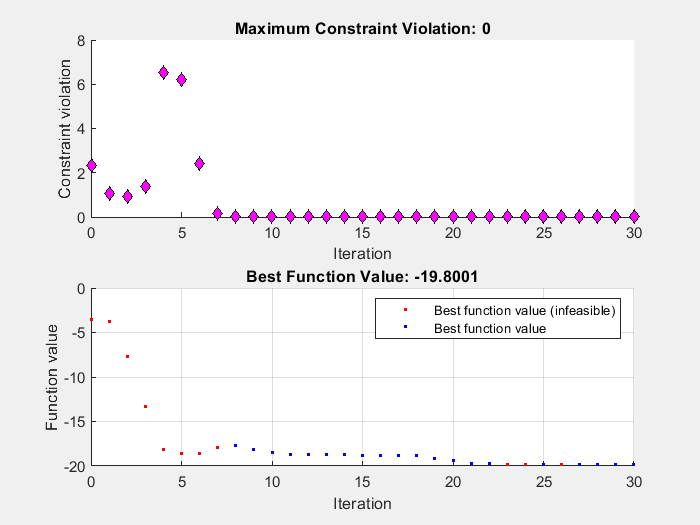


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


[finalValues,maxScore] = solve(designprob,initialValues,'Options',options);

maxScore

maxScore = 19.8001

% reset path
rmpath('Aerodynamic Coefficients');
rmpath('Mass Moment of Inertia');